# a) Secular equilibrium:(self made solver)

#  
$${^{144}Ce- {^{144}Pr$$


clc,clearvars,clf

tHalfP=284.893*24*3600; %half life of parent(Ce-144),second
tHalfD=17.29*60;   %half life of progeny(Pr-144),second
lambdaP=log(2)/tHalfP; %decay constant of parent
lambdaD=log(2)/tHalfD; %decay constant of progeny

%differential equations
dN1=@(t,NP,ND)(-lambdaP)*NP;
dN2=@(t,NP,ND) lambdaP*NP-lambdaD*ND;
%using rk4 function to solve the system of ODE
[t,NP,ND]=rk4(dN1,dN2,0,10000,1/lambdaP,0,80);


%activity
AP=lambdaP*NP;
AD=lambdaD*ND;

#### Plotting activity vs. time graph

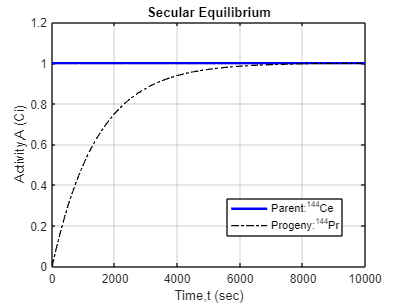

plot(t,AP,'b','linewidth',2) %plotting parent activity vs. time
axis([0 10000 0 1.2]) %axis scaling for better appearance
hold on
plot(t,AD,'k-.','linewidth',1) %plotting progeny activity vs. time
xlabel('Time,t (sec)')
ylabel('Activity,A (Ci)')
legend('Parent:^{144}Ce','Progeny:^{144}Pr')
title('Secular Equilibrium')
grid on

legend("Position", [0.56323,0.22338,0.28508,0.12018])